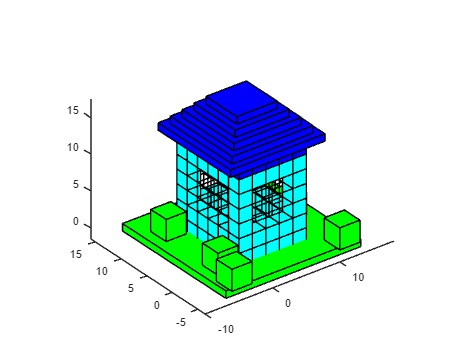

verticesCube = [
    -1, 1, 1, -1, -1, 1, 1, -1;
    -1, -1, 1, 1, -1, -1, 1, 1;
    -1, -1, -1, -1, 1, 1, 1, 1;
    1, 1, 1, 1, 1, 1, 1, 1
    ];

facesCube = [
    1, 2, 6, 5;
    2, 3, 7, 6;
    3, 4, 8, 7;
    4, 1, 5, 8;
    1, 2, 3, 4;
    5, 6, 7, 8
    ];


move1X = [
    1, 0, 0, 2;
    0, 1, 0, 0;
    0, 0, 1, 0;
    0, 0, 0, 1
    ];
move1Y = [
    1, 0, 0, 0;
    0, 1, 0, 2;
    0, 0, 1, 0;
    0, 0, 0, 1
    ];
move1Z = [
    1, 0, 0, 0;
    0, 1, 0, 0;
    0, 0, 1, 2;
    0, 0, 0, 1
    ];

% построение стен и основания
cube_1 = verticesCube;

for i = 1:5
    DrawShape(cube_1, facesCube, 'c');
    cube_2 = cube_1;
    for j = 1:5
        cube_2 = move1Y * cube_2;
        DrawShape(cube_2, facesCube, 'c');
        if (j == 5) || (i == 1) || (i == 5)
             cube_3 = cube_2;
             for k = 1:5
                cube_3 = move1Z * cube_3;
                if ((k == 5) || (k == 1) || (i == 5) || (i == 1)) && (j == 5) ||(k == 5) || (k == 1)
                    DrawShape(cube_3, facesCube, 'c');
                else
            %DrawEmpShape(cube_3);
                DrawShapeEmp(cube_3, facesCube, 'w');
                end
             end
              cube_3 = move1Z * cube_2;
        DrawShape(cube_3, facesCube, 'c');
        end
    end
    cube_3 = cube_1;
    for k = 1:5
        cube_3 = move1Z * cube_3;
        if (i == 1) || (i == 5) ||(k == 5) || (k == 1)
            DrawShape(cube_3, facesCube, 'c');
        else
            %DrawEmpShape(cube_3);
            DrawShapeEmp(cube_3, facesCube, 'w');
        end
    end
    cube_1 = move1X * cube_1;
end

% построение крыши

roof1 = verticesCube;

for i = 1:6
    roof1 = move1Z * roof1;
end

for j = 1:5
    DrawShape (roof1, facesCube, 'b')
    roof2 = roof1;
    for k = 1:5
        roof2 = move1Y * roof2;
        DrawShape (roof2, facesCube, 'b')
    end
    roof1 = move1X * roof1;
end

size1 = [
    7, 0, 0, 0;
    0, 7, 0, 0;
    0, 0, 0.5, 0;
    0, 0, 0, 1
    ];

roof3 = size1 * verticesCube;
moveRoof1 = [
     1, 0, 0, 4;
    0, 1, 0, 5;
    0, 0, 1, 13;
    0, 0, 0, 1
    ];
roof3 = moveRoof1 * roof3;
DrawShape (roof3, facesCube, 'b')

size2 = [
    6, 0, 0, 0;
    0, 6, 0, 0;
    0, 0, 0.5, 0;
    0, 0, 0, 1
    ];

roof4 = size2 * verticesCube;
moveRoof2 = [
     1, 0, 0, 4;
    0, 1, 0, 5;
    0, 0, 1, 14;
    0, 0, 0, 1
    ];
roof4 = moveRoof2 * roof4;
DrawShape (roof4, facesCube, 'b')

size3 = [
    5, 0, 0, 0;
    0, 5, 0, 0;
    0, 0, 0.5, 0;
    0, 0, 0, 1
    ];

roof5 = size3 * verticesCube;
moveRoof3 = [
    1, 0, 0, 4;
    0, 1, 0, 5;
    0, 0, 1, 15;
    0, 0, 0, 1
    ];
roof5 = moveRoof3 * roof5;
DrawShape (roof5, facesCube, 'b')


size4 = [
    4, 0, 0, 0;
    0, 4, 0, 0;
    0, 0, 0.5, 0;
    0, 0, 0, 1
    ];

roof6 = size4 * verticesCube;
moveRoof4 = [
    1, 0, 0, 4;
    0, 1, 0, 5;
    0, 0, 1, 16;
    0, 0, 0, 1
    ];
roof6 = moveRoof4 * roof6;
DrawShape (roof6, facesCube, 'b')


size5 = [
    3, 0, 0, 0;
    0, 3, 0, 0;
    0, 0, 0.5, 0;
    0, 0, 0, 1
    ];

roof7 = size5 * verticesCube;
moveRoof5 = [
    1, 0, 0, 4;
    0, 1, 0, 5;
    0, 0, 1, 17;
    0, 0, 0, 1
    ];
roof7 = moveRoof5 * roof7;
DrawShape (roof7, facesCube, 'b')

% зададим растения вокруг дома

sizePt1 = [
    10, 0, 0, 0;
    0, 10, 0, 0;
    0, 0, 0.5, 0;
    0, 0, 0, 1
    ];

earth = sizePt1 * verticesCube;

moveEarth = [
     1, 0, 0, 4;
    0, 1, 0, 5;
    0, 0, 1, -1;
    0, 0, 0, 1
    ];

earth = moveEarth * earth;

DrawShape(earth, facesCube, 'g')

sizePt = [
    1.5, 0, 0, 0;
    0, 1.5, 0, 0;
    0, 0, 1.5, 0;
    0, 0, 0, 1
    ];

mPt1 = [
    1, 0, 0, -4;
    0, 1, 0, -4;
    0, 0, 1, 1;
    0, 0, 0, 1
    ];

mPt2 = [
    1, 0, 0, -3;
    0, 1, 0, 0;
    0, 0, 1, 1;
    0, 0, 0, 1
    ];

mPt3 = [
    1, 0, 0, -3;
    0, 1, 0, 10;
    0, 0, 1, 1;
    0, 0, 0, 1
    ];
mPt4 = [
    1, 0, 0, 12;
    0, 1, 0, -4;
    0, 0, 1, 1;
    0, 0, 0, 1
    ];
mPt5 = [
    1, 0, 0, 11;
    0, 1, 0, 5;
    0, 0, 1, 1;
    0, 0, 0, 1
    ];

DrawShape (mPt1 * sizePt * verticesCube, facesCube, 'g')
DrawShape (mPt2 * sizePt * verticesCube, facesCube, 'g')
DrawShape (mPt3 * sizePt * verticesCube, facesCube, 'g')
DrawShape (mPt4 * sizePt * verticesCube, facesCube, 'g')
DrawShape (mPt5 * sizePt * verticesCube, facesCube, 'g')

%DrawShape (verticesCube, facesCube, 'c')
axis equal;
%view(90, 0);
view(3);

function DrawShape(vertices, faces, color)
    patch('Vertices', (vertices(1:3,:)./vertices(4,:))','Faces', faces, 'FaceColor', color);

end

function DrawShapeEmp(vertices, faces, color)
    patch('Vertices', (vertices(1:3,:)./vertices(4,:))','Faces', faces, 'FaceColor', color);
    hidden off;

end


